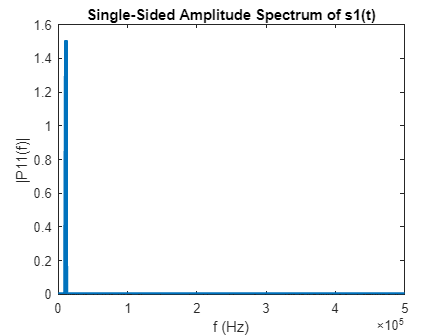

Fs = 1000000; % Sampling frequency
T = 1/Fs; % Sampling period


% Signals to use in the osciloscope
% s1 = 1.5*sin(2*pi*11000*t); % Signal 1
% s2 = 1.5*sin(2*pi*12000*t); % Signal 2
% s3 = 1.5*square(2*pi*11000*t); % Signal 3

% Signal 1
L = 50000; % Legth of signal
t = (0:L-1)*T; % Time vector
s1 = 1.5*sin(2*pi*11000*t); % Signal 1
Y1 = fft(s1);
P21 = abs(Y1/L);
P11 = P21(1:L/2+1);
P11(2:end-1) = 2*P11(2:end-1);
f = Fs/L*(0:(L/2));

plot(f,P11,"LineWidth",3)
title("Single-Sided Amplitude Spectrum of s1(t)")
xlabel("f (Hz)")
ylabel("|P11(f)|")

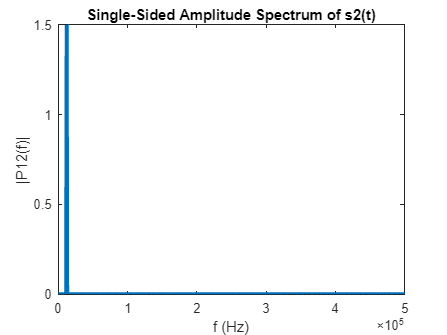


% Signal 2
L = 50000; % Legth of signal
t = (0:L-1)*T; % Time vector
s2 = 1.5*sin(2*pi*12000*t); % Signal 2
Y2 = fft(s2);
P22 = abs(Y2/L);
P12 = P22(1:L/2+1);
P12(2:end-1) = 2*P12(2:end-1);
f = Fs/L*(0:(L/2));

plot(f,P12,"LineWidth",3)
title("Single-Sided Amplitude Spectrum of s2(t)")
xlabel("f (Hz)")
ylabel("|P12(f)|")

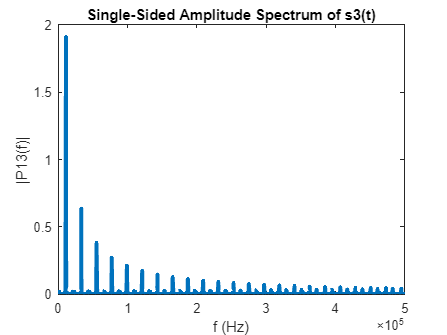


% Signal 3
L = 50000; % Legth of signal
t = (0:L-1)*T; % Time vector
s3 = 1.5*square(2*pi*11000*t); % Signal 3
Y3 = fft(s3);
P23 = abs(Y3/L);
P13 = P23(1:L/2+1);
P13(2:end-1) = 2*P13(2:end-1);
f = Fs/L*(0:(L/2));

plot(f,P13,"LineWidth",3)
title("Single-Sided Amplitude Spectrum of s3(t)")
xlabel("f (Hz)")
ylabel("|P13(f)|")

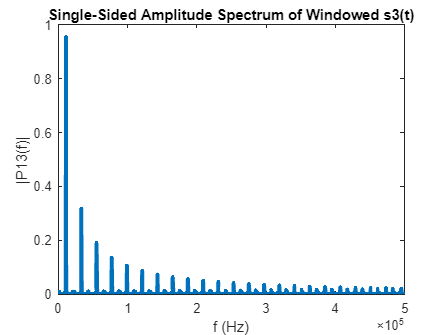


% Windowed Signal 3
L = 50000; % Legth of signal
t = (0:L-1)*T; % Time vector
% s3.*hann(L); % Signal 3 with hanning window
Y3 = fft(s3.*hann(L)');
P23 = abs(Y3/L);
P13 = P23(1:L/2+1);
P13(2:end-1) = 2*P13(2:end-1);
f = Fs/L*(0:(L/2));

plot(f,P13,"LineWidth",3)
title("Single-Sided Amplitude Spectrum of Windowed s3(t)")
xlabel("f (Hz)")
ylabel("|P13(f)|")